% This file verify tha the PID design and tuning give a correct output:

% 1) Step response verification in CST. step, stepinfo and margin commands are used 
% to verify the PID coefficients, considering:
% SettlingTime (must be lower or equal to 0.15 s)
% Overshoot ( must be lower or equal to 10% 
% Phase margin (near 60°)
% Cut off frequency (near 33 rad/s)

% 2) Verification of the step unitary response using a simplified simulink
% model: step_pid.slx (This model is not required in the assignments).

% 3) Verification of the step response using simulink Lab_0_sim.slx
% Lab_0_sim.slx contains the model required at point 2.1 in the Laboratory
% assignments. Steps amplitude: 10° 30° 50° 90° 180° 360° 

% Create the pid transfer function and the feedback transfer function

pid_tf = kp + ki/s + (kd*s)/(tl*s+1);

[num_pid, den_pid] = tfdata(pid_tf, 'v');

feedback_tf = feedback(pid_tf*P, 1);



## PID verification

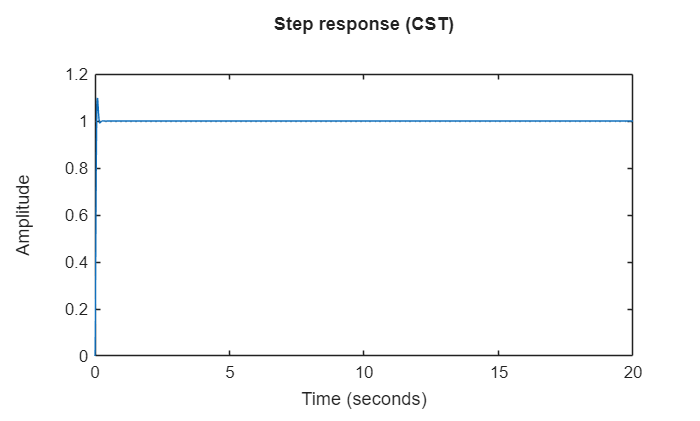



% Verify specifications using stepinfo 

figure;
step(feedback_tf,20 );
title('Step response (CST)');

stepinfo(feedback_tf,'SettlingTimeThreshold', 0.05 )

ans = struct with fields:
         RiseTime: 0.0426
    TransientTime: 0.1229
     SettlingTime: 0.1229
      SettlingMin: 0.9125
      SettlingMax: 1.0989
        Overshoot: 9.8873
       Undershoot: 0
             Peak: 1.0989
         PeakTime: 0.0904


## Verify phase margin and cut off frequency (must be near 60° and wgc near 33 rad/s)

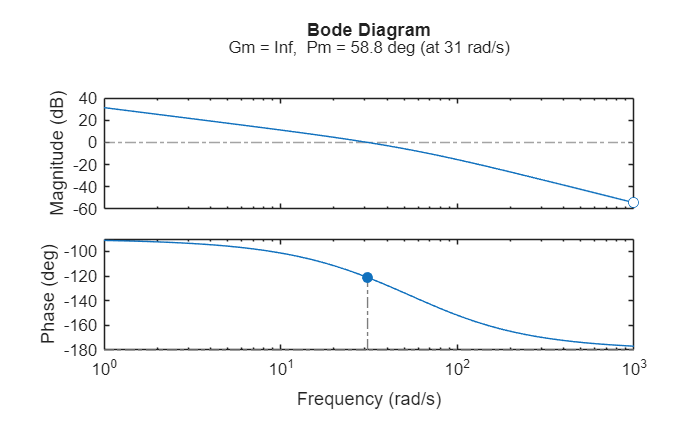


figure;
margin(pid_tf*P);

## Verify the response in a simulink simplified model:

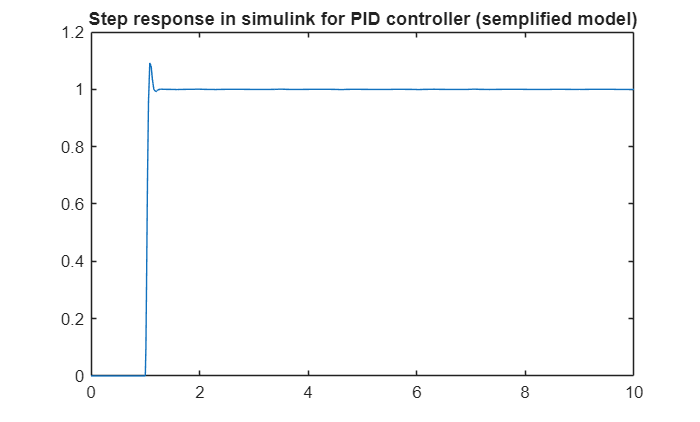



%run simulation 
sim('step_pid.slx');     
step_pid_response.t = ans.Step_pid.time;
step_pid_response.v = ans.Step_pid.signals.values;

%Data plotting
figure
plot(step_pid_response.t, step_pid_response.v)
title('Step response in simulink for PID controller (semplified model)')

## Step response with simulink model (LAB_0_sim.slx) with amplitude 10, 30, 50, 90, 180, 360 deg (Point 2.1)

% Remarks: the output is not so good for 10° 30°

% Define the step amplitude vector

step_amplitudes = [10, 30, 50, 90, 180, 360];

% For loop. Run LAB_0_sim.slx with different amplitudes
for i = 1:length(step_amplitudes)

    step_gain = step_amplitudes(i);
    simOut = sim('Black_box_system.slx');
    
    % Create plots
    figure; 
    plot(simOut.th, 'LineWidth', 1.5);
    grid on;
    title(sprintf('Step response in simulink (Black_box_system.slx) , Amplitude = %d°', step_gain));
    xlabel('Time [s]');
    ylabel('Position [deg]');
    
    % Save data and plots (optional)

    % save data
    % base_name = sprintf('step_response_%d', step_gain);
    % save([base_name, '.mat'], 'simOut');
    
    % save the plots
    % saveas(gcf, [base_name, '.png']); 

    drawnow; 
end

### Searching for referenced models in model 'Black_box_system'.
### Total of 0 models to build.


### Searching for referenced models in model 'Black_box_system'.
### Total of 0 models to build.


### Searching for referenced models in model 'Black_box_system'.
### Total of 0 models to build.


### Searching for referenced models in model 'Black_box_system'.
### Total of 0 models to build.


### Searching for referenced models in model 'Black_box_system'.
### Total of 0 models to build.


### Searching for referenced models in model 'Black_box_system'.
### Total of 0 models to build.
